## Rete Anticipatrice

Definizione del **numeratore** e del **denominatore** della **FdT P(s)**.

num = 99;
den = conv([0.001 1],conv([1 1],[0.1 1]));

P_s = tf(num,den)


P_s =
 
                   99
  -------------------------------------
  0.0001 s^3 + 0.1011 s^2 + 1.101 s + 1
 
Continuous-time transfer function.
Model Properties


Determinare una **rete correttrice** affinchè:

- **Pulsazione di attraversamento**: wt > 70 [rad/s]

- **Margine di fase**: mf > 40°

Calcolo del **Margine di Guadagno** e** di Fase **della funzione **P(s)**.

- Dal diagramma si nota che nessuno dei due requisti è soddisfatto.

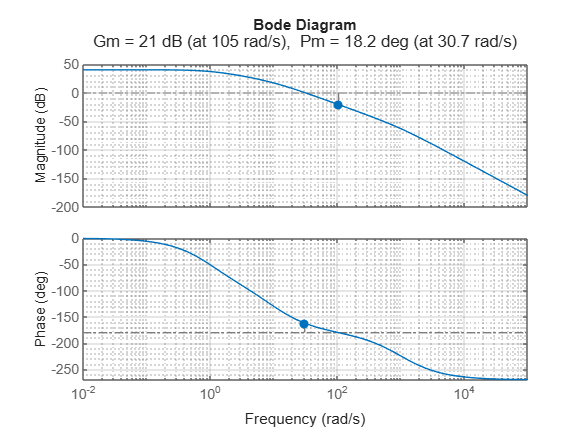

margin(P_s);
grid on
grid minor

**Rete correttrice.**

- Una possibile soluzione è l'introduzione di una **Rete anticipatrice** per aumentare sia il **margine di fase** che la **pulsazione di attraversamento**.

- Osservando il diagramma, si nota che il polo **0.1s+1** è responsabile della riduzione del margine di fase alla pulsazione **s=1/(-10)=-10**. Allora alla rete anticipatrice si aggiunge uno **zero** per eliminare quel polo.

- Alla rete anticipatrice si aggiunge un **polo** alla pulsazione di **100 rad/s (s=-100)** per aumentare (spostare a destra) la pulsazione di attraversamento.

- Dal **polo** **p=1/tau** si calcola **tau** --> **tau=1/p=0.01** --> polo della rete correttrice: **0.01s+1**. 

- lo **zero** da implementare nella rete correttrice deve avere la forma **0.1s+1. **Lo zero nella forma base deve essere del tipo **alfa*tau*s+1 **--> dal momento che **tau** è già stato calcolato precedentemente e vale 0.01 --> **alfa=10. **Si ottiene quindi **0.01*10s+1= 0.1s+1.**

K = 10;
alfa = 10;
tau = 0.01;

num = (K/alfa)*[alfa*tau 1];
den = [tau 1];

G_s = tf(num,den);

**Funzione ad anello aperto complessiva F(s).**

- **F(s) = G(s)P(s).**

- Dal diagramma si nota che entrambi i requisiti sono soddisfatti.

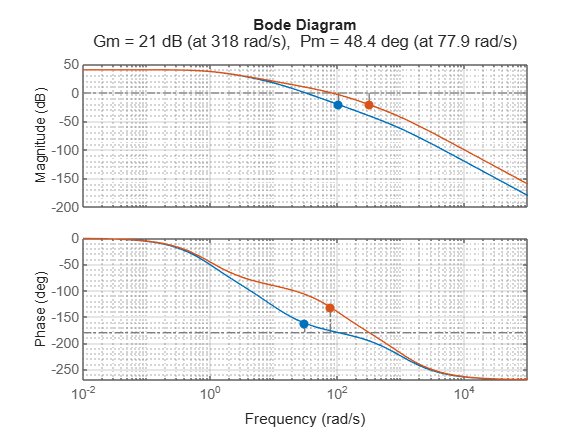

F_s = G_s*P_s;

hold on
margin(F_s)
grid on
grid minor

**Domanda**: nel caso in cui non si volesse aumentare la pulsazione di attraversamento ma tenerla costante, su quale parametro del compensatore si può agire?

- Lasciando la **rete anticipatrice G(s)** inalterata, per ridurre la pulsazione di attraversamento e quindi riportarla al valore iniziale, è sufficiente ridurre il **guadagno** **K**. Osservando il diagramma di Bode, riducendo il guadagno, la curva si abbassa portando verso sinistra (e quindi riducendo) la pulsazione di attraversamento. Si introduce una nuova rete anticipatrice **K(s)** con caratteristiche uguali alla precente, solo con** K** ridotto.

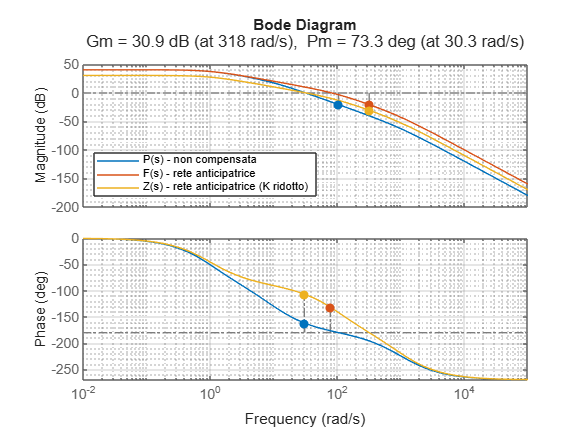

K_r = 3.2;
alfa = 10;
tau = 0.01;

num = (K_r/alfa)*[alfa*tau 1];
den = [tau 1];

K_s = tf(num,den);

Z_s = K_s*P_s;

hold on
margin(Z_s)
grid on
grid minor
hold off
legend("P(s) - non compensata","F(s) - rete anticipatrice", "Z(s) - rete anticipatrice (K_r ridotto)");
legend("Location","southwest");